# **Calculation of Number of Sites Based on Coverage**

## To Get Number of Sites Required to Cover a Certain Area:

## First Step : Calculate Path Loss.

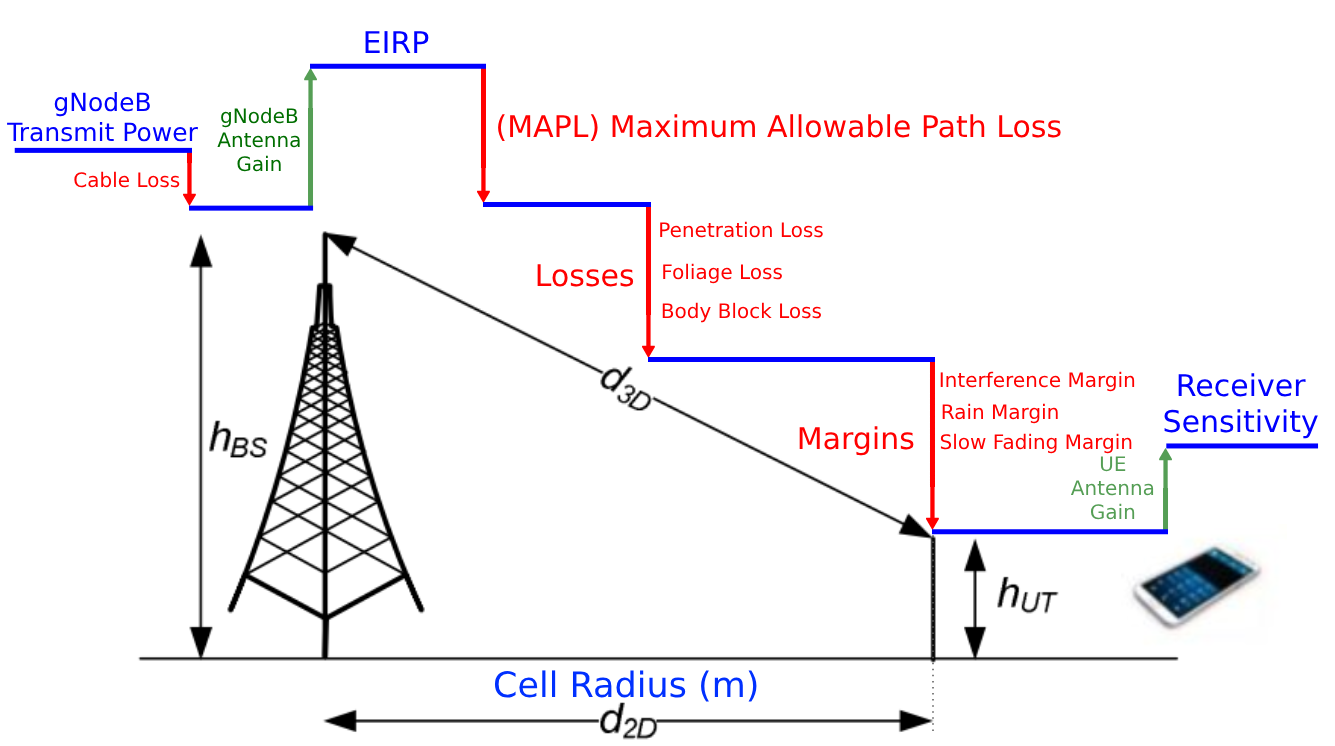

### 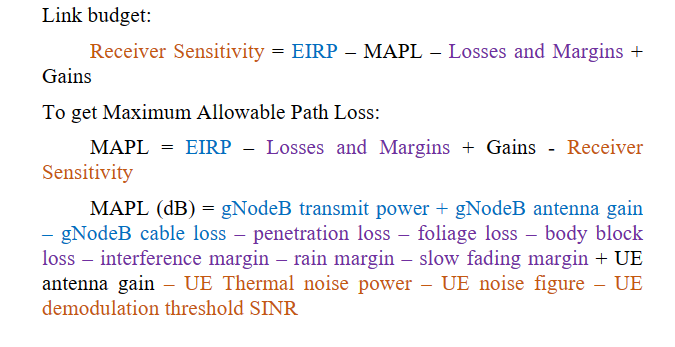

#### **        1-gNodeB Parameters (EIRP):**

- gNodeB Transmit Power.

- gNodeB Antenna Gain.

- gNodeB Cable Loss.

#### **        2-UE Parameters (Receiver Sensitivity):**

- UE Thermal Noise Power.

- UE Noise Figure.

- UE Demodulation Threshold SINR.

- UE Antenna Gain.

####         3-Losses and Margins:

- Penetration Loss.

- Foliage Loss.

- Body Loss.

- Interference Margin.

- Rain Margin.

- Slow Fading Margin.

## Second Step : Use a Proper Propagation Model to Calculate Cell Radius.

####         Available Propagation Models in This Script:

- **3GPP 38.901 : **formula taken from 3GPP TR 38.901 version 17.0.0.

- **3GPP 38.900 : **formula taken from 3GPP TR 38.900 version 15.0.0.

- **Free Space Path Loss : **The free-space path loss (FSPL) formula.

- **Okumura-Hata : **formula taken from Atoll user manual.

- **Cost-Hata : **formula taken from Atoll user manual.

- **Standard Propagation Model : **formula taken from Atoll user manual.

## Last Step : Calculate Site Area, Then Divide Total Area By Site Area to Get Number of Sites.

# Calculations:

# **General Parameters:**

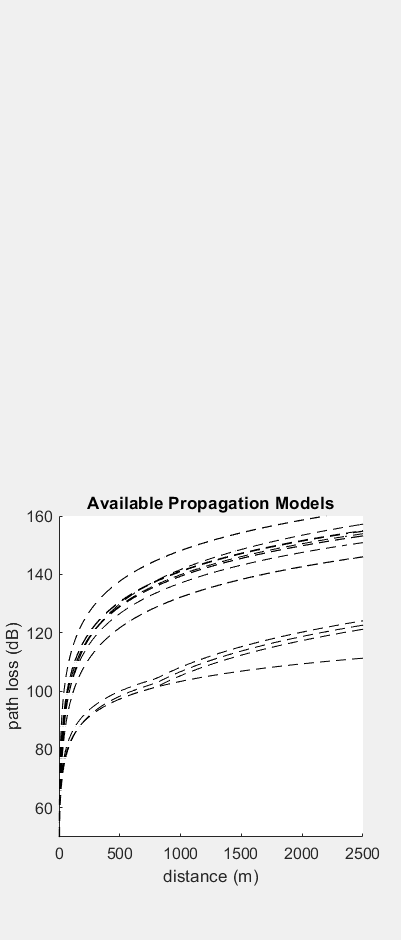

Frequency=5;
Bandwidth=80000000;
UE_height=1.5;
TX_height=35;
Frequencies=[0.8 1.8 2.1 2.6 3.5 4.5 28 39];

pmsbool=true;

if pmsbool==true
    p_x=0:160;
    p_ys=zeros(19,161);
    p_c=1;
    for i=p_x
        %3GPP 38.901
        p_ys(1,p_c)=TR_3GPP_38901("UMa","NLOS",i,Frequencies(Frequency),TX_height,UE_height);
        p_ys(2,p_c)=TR_3GPP_38901("UMa","LOS",i,Frequencies(Frequency),TX_height,UE_height);
        p_ys(3,p_c)=TR_3GPP_38901("UMi","NLOS",i,Frequencies(Frequency),TX_height,UE_height);
        p_ys(4,p_c)=TR_3GPP_38901("UMi","LOS",i,Frequencies(Frequency),TX_height,UE_height);
        %3GPP 38.900
        p_ys(5,p_c)=TR_3GPP_38900("UMa","NLOS",i,Frequencies(Frequency),TX_height,UE_height);
        p_ys(6,p_c)=TR_3GPP_38900("UMa","LOS",i,Frequencies(Frequency),TX_height,UE_height);
        p_ys(7,p_c)=TR_3GPP_38900("UMi","NLOS",i,Frequencies(Frequency),TX_height,UE_height);
        p_ys(8,p_c)=TR_3GPP_38900("UMi","LOS",i,Frequencies(Frequency),TX_height,UE_height);
        %Okumura-Hata
        p_ys(9,p_c)=Hata("Okumura","Urban Large Cities",i,Frequencies(Frequency)*1000,TX_height,UE_height)*1000;
        p_ys(10,p_c)=Hata("Okumura","Urban Small Cities",i,Frequencies(Frequency)*1000,TX_height,UE_height)*1000;
        p_ys(11,p_c)=Hata("Okumura","Suburban Large Cities",i,Frequencies(Frequency)*1000,TX_height,UE_height)*1000;
        p_ys(12,p_c)=Hata("Okumura","Suburban Small Cities",i,Frequencies(Frequency)*1000,TX_height,UE_height)*1000;
        %Cost-Hata
        p_ys(13,p_c)=Hata("Cost","Urban Large Cities",i,Frequencies(Frequency)*1000,TX_height,UE_height)*1000;
        p_ys(14,p_c)=Hata("Cost","Urban Small Cities",i,Frequencies(Frequency)*1000,TX_height,UE_height)*1000;
        p_ys(15,p_c)=Hata("Cost","Suburban Large Cities",i,Frequencies(Frequency)*1000,TX_height,UE_height)*1000;
        p_ys(16,p_c)=Hata("Cost","Suburban Small Cities",i,Frequencies(Frequency)*1000,TX_height,UE_height)*1000;
        %Free Space Path Loss
        p_ys(17,p_c)=10^(i/20)*(physconst('LightSpeed')/(Frequencies(Frequency)*1e9))*(1/(4*pi));
        %Standard Propagation Model
        Clutter_Losses=table2array(readtable("clutter_losses.txt")).';
        p_ys(18,p_c)=SPM(i,Frequencies(Frequency)*1000,TX_height,UE_height,"clutter_2m.grc",Clutter_Losses);
        p_ys(19,p_c)=SPM(i,Frequencies(Frequency)*1000,TX_height,UE_height);
        
        p_c=p_c+1;
    end
    
    if exist("f1","var") && isvalid(f1)
        set(0,"CurrentFigure",f1);
    else
        f1=figure("Name","Propagation Model","Visible","on","WindowStyle","docked",'NumberTitle','off');
    end
    
    subplot(2,1,2,"replace");
    
    p_s=gobjects(19);
    hold("on");
    for i=1:19
        p_s(i)=plot(p_ys(i,:),p_x,"--k");
    end
    hold("off");
    xlabel("distance (m)");
    ylabel("path loss (dB)");
    title("Available Propagation Models");
    xlim([0 2500]);
    ylim([50 160]);

else
    if exist("f1","var") && isvalid(f1)
        set(0,"CurrentFigure",f1);
    else
        f1=figure("Name","Propagation Model","Visible","on","WindowStyle","docked",'NumberTitle','off');
    end
    subplot(2,1,2,"replace");
end

# **gNodeB Parameters (EIRP):**

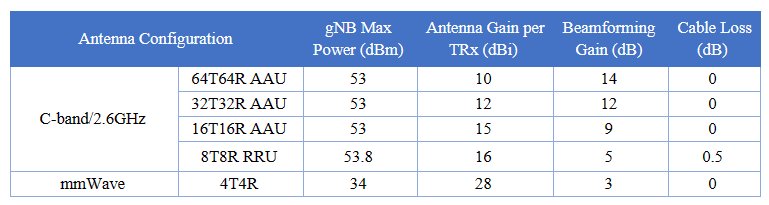

gNodeBAntenna=1;

### gNodeB Transmit Power:

gNodeB_transmit_powers=[53 53 53 53.8 34];
gNodeB_transmit_power=gNodeB_transmit_powers(gNodeBAntenna);

gNodeB_transmit_power = gNodeB_transmit_power + double(false)*(50 - gNodeB_transmit_power);

disp("gNodeB Transmit Power = "+gNodeB_transmit_power+"dBm")

gNodeB Transmit Power = 53dBm


### gNodeB Antenna Gain:

Beamforming=true;
gNodeB_beamforming_gains=[14 12 9 5 3];
gNodeB_antenna_gains=[10 12 15 16 28];
if Beamforming==true
    gNodeB_antenna_gain=gNodeB_beamforming_gains(gNodeBAntenna)+gNodeB_antenna_gains(gNodeBAntenna);
else
    gNodeB_antenna_gain=gNodeB_antenna_gains(gNodeBAntenna);
end

gNodeB_antenna_gain = gNodeB_antenna_gain + double(false)*(24 - gNodeB_antenna_gain);

%gNodeB_antenna_gain=21;
disp("gNodeB Antenna Gain = "+gNodeB_antenna_gain+"dBi")

gNodeB Antenna Gain = 24dBi


### gNodeB Cable Loss :

gNodeB_cable_losses=[0 0 0 0.5 0];
gNodeB_cable_loss=gNodeB_cable_losses(gNodeBAntenna);

gNodeB_cable_loss = gNodeB_cable_loss + double(false)*(0 - gNodeB_cable_loss);

disp("gNodeB Cable Loss = "+gNodeB_cable_loss+"dB")

gNodeB Cable Loss = 0dB


EIRP=gNodeB_transmit_power+gNodeB_antenna_gain-gNodeB_cable_loss;
disp("EIRP (Effective Isotropic Radiated Power) ="+ EIRP +"dB")

EIRP (Effective Isotropic Radiated Power) =77dB


# **UE Parameters (Receiver Sensitivity):**

### UE Antenna Gain:

UE_antenna_gain=0;
disp("UE Antenna Gain = "+UE_antenna_gain+"dB")

UE Antenna Gain = 0dB


### UE Thermal Noise Power:

## 
$$\textrm{Thermal}\;\textrm{noise}\;\textrm{power}\;\left(\textrm{dBm}\right)=-174+10\log \left(\textrm{"Bandwidth"}\textrm{Hz}\right)$$


UE_Thermal_noise_power=-174+10*log10(Bandwidth);

UE_Thermal_noise_power = UE_Thermal_noise_power + double(false)*(-100 - UE_Thermal_noise_power);

disp("UE Thermal Noise Power = "+UE_Thermal_noise_power+"dBm")

UE Thermal Noise Power = -94.9691dBm


### UE Noise Figure:

## Typical Value for Noise Figure at UE is 7dB.

UE_noise_figure=7;
disp("UE Noise Figure = "+UE_noise_figure+"dB")

UE Noise Figure = 7dB


### UE SINR:

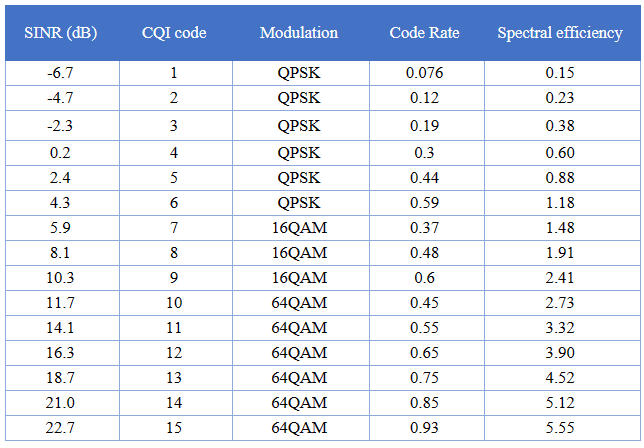

UE_demodulation_threshold_SINR=-6.7;

UE_demodulation_threshold_SINR = UE_demodulation_threshold_SINR + double(false)*(-2 - UE_demodulation_threshold_SINR);

%UE_demodulation_threshold_SINR=-2;
disp("UE Demodulation Threshold SINR = "+UE_demodulation_threshold_SINR+"dB")

UE Demodulation Threshold SINR = -6.7dB


Receiver_Sensitivity = UE_Thermal_noise_power+UE_noise_figure+UE_demodulation_threshold_SINR;
disp("Receiver Sensitivity ="+ Receiver_Sensitivity +"dB")

Receiver Sensitivity =-94.6691dB


# **Losses and Margins:**

### Penetration Loss:

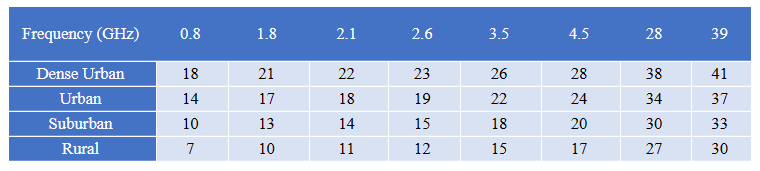

Environment=2;
penetration_losses=[18 21 22 23 26 28 38 41; 14 17 18 19 22 24 34 37; 10 13 14 15 18 20 30 33; 7 10 11 12 15 17 27 30];
penetration_loss=penetration_losses(Environment,Frequency);

penetration_loss = penetration_loss + double(true)*(10 - penetration_loss);

%penetration_loss=10;
disp("Penetration Loss = "+penetration_loss+"dB")

Penetration Loss = 10dB


### Foliage Loss:

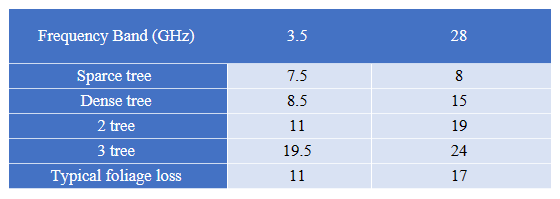

foliage_losses=[7.5 8.5 11 19.5 11; 8 15 19 24 17];
foliage_loss_type=2;
if Frequency>6
    foliage_loss=foliage_losses(2,foliage_loss_type);
else
    foliage_loss=foliage_losses(1,foliage_loss_type);
end

foliage_loss = foliage_loss + double(false)*(3 - foliage_loss);

%foliage_loss=3;
disp("Foliage Loss = "+foliage_loss+"dB")

Foliage Loss = 8.5dB


### Body Loss:

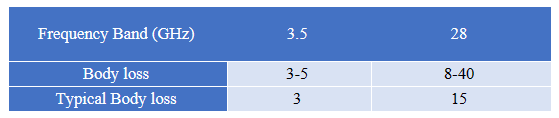

if Frequency>6
    body_block_loss_min=8;
    body_block_loss_max=40;
    body_block_loss_def=15;
else
    body_block_loss_min=3;
    body_block_loss_max=5;
    body_block_loss_def=3;
end
body_block_loss=3;
disp("Body Loss = "+body_block_loss+"dB")

Body Loss = 3dB



Losses = penetration_loss + foliage_loss + body_block_loss;
disp("Medium Losses ="+ Losses +"dB")

Medium Losses =21.5dB


### Interference Margin:

if Frequency>6
    interference_margin=1;
else
    interference_margin=6;
end

interference_margin = interference_margin + double(false)*(3 - interference_margin);

%interference_margin=3;
disp("Interference Margin = "+interference_margin+"dB")

Interference Margin = 6dB


### Rain Margin:

if Frequency>6
    rain_margin_def=3;
else
    rain_margin_def=0;
end
rain_margin=0;
disp("Rain Margin = "+rain_margin+"dB")

Rain Margin = 0dB


### Slow Fading Margin:

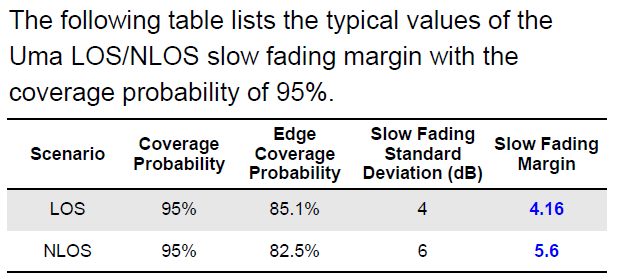

slow_fading_margin=5.6;

slow_fading_margin = slow_fading_margin + double(false)*(8 - slow_fading_margin);

%slow_fading_margin=8;
disp("Slow Fading Margin = "+slow_fading_margin+"dB")

Slow Fading Margin = 5.6dB




Margins = interference_margin + rain_margin + slow_fading_margin;
disp("Margins ="+ Margins +"dB")

Margins =11.6dB


# Path Loss:

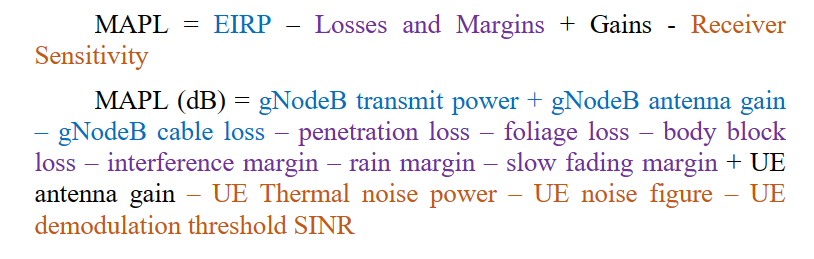

MAPL=  EIRP ...
            -Losses...
            -Margins...
            +UE_antenna_gain ...
            -Receiver_Sensitivity;
disp("MAPL Maximum Allowable Path Loss= "+MAPL+"dB")

MAPL Maximum Allowable Path Loss= 138.5691dB


# Propagation Model:

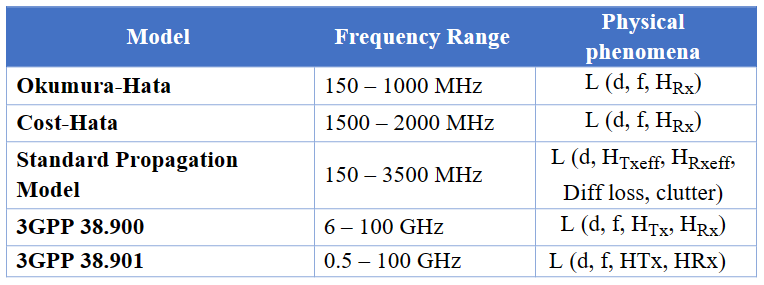

pm="3GPP 38.901";
switch (pm)
    case "3GPP 38.901"
        senarios=["UMa NLOS","UMa LOS","UMi NLOS","UMi LOS"];
    case "3GPP 38.900"
        senarios=["UMa NLOS","UMa LOS","UMi NLOS","UMi LOS"];
    case "Okumura-Hata"
        senarios=["Urban Large Cities","Urban Small Cities","Suburban Large Cities","Suburban Small Cities"];
    case "Cost-Hata"
        senarios=["Urban Large Cities","Urban Small Cities","Suburban Large Cities","Suburban Small Cities"];
    case "Free Space Path Loss"
        senarios=[" "," "," "," "];
    case "Standard Propagation Model"
        senarios=["Without Clutter","With Clutter","Without Clutter","With Clutter"];
end
senario=senarios(3);


if pmsbool==true
    for i=1:19
        p_s(i).LineStyle="--";
        p_s(i).LineWidth=0.5;
        p_s(i).Color="k";
    end
end
switch (pm)
    case "3GPP 38.901"
        s0=senario.split(" ");
        s1=s0(1);
        s2=s0(2);
        Cell_Range=TR_3GPP_38901(s1,s2,MAPL,Frequencies(Frequency),TX_height,UE_height);
        if pmsbool==true
            switch(senario)
                case("UMa NLOS")
                    p_s(1).LineStyle="-";
                    p_s(1).LineWidth=1.5;
                    p_s(1).Color="m";
                case("UMa LOS")
                    p_s(2).LineStyle="-";
                    p_s(2).LineWidth=1.5;
                    p_s(2).Color="m";
                case("UMi NLOS")
                    p_s(3).LineStyle="-";
                    p_s(3).LineWidth=1.5;
                    p_s(3).Color="m";
                case("UMi LOS")
                    p_s(4).LineStyle="-";
                    p_s(4).LineWidth=1.5;
                    p_s(4).Color="m";
            end 
        end
    case "3GPP 38.900"
        s0=senario.split(" ");
        s1=s0(1);
        s2=s0(2);
        Cell_Range=TR_3GPP_38900(s1,s2,MAPL,Frequencies(Frequency),TX_height,UE_height);
        if pmsbool==true
            switch(senario)
                case("UMa NLOS")
                    p_s(5).LineStyle="-";
                    p_s(5).LineWidth=1.5;
                    p_s(5).Color="m";
                case("UMa LOS")
                    p_s(6).LineStyle="-";
                    p_s(6).LineWidth=1.5;
                    p_s(6).Color="m";
                case("UMi NLOS")
                    p_s(7).LineStyle="-";
                    p_s(7).LineWidth=1.5;
                    p_s(7).Color="m";
                case("UMi LOS")
                    p_s(8).LineStyle="-";
                    p_s(8).LineWidth=1.5;
                    p_s(8).Color="m";
            end
        end
    case "Okumura-Hata"
        Cell_Range=Hata("Okumura",senario,MAPL,Frequencies(Frequency)*1000,TX_height,UE_height)*1000;
        if pmsbool==true
            switch(senario)
                case("Urban Large Cities")
                    p_s(9).LineStyle="-";
                    p_s(9).LineWidth=1.5;
                    p_s(9).Color="m";
                case("Urban Small Cities")
                    p_s(10).LineStyle="-";
                    p_s(10).LineWidth=1.5;
                    p_s(10).Color="m";
                case("Suburban Large Cities")
                    p_s(11).LineStyle="-";
                    p_s(11).LineWidth=1.5;
                    p_s(11).Color="m";
                case("Suburban Small Cities")
                    p_s(12).LineStyle="-";
                    p_s(12).LineWidth=1.5;
                    p_s(12).Color="m";
            end
        end
    case "Cost-Hata"
        Cell_Range=Hata("Cost",senario,MAPL,Frequencies(Frequency)*1000,TX_height,UE_height)*1000;
        if pmsbool==true
            switch(senario)
                case("Urban Large Cities")
                    p_s(13).LineStyle="-";
                    p_s(13).LineWidth=1.5;
                    p_s(13).Color="m";
                case("Urban Small Cities")
                    p_s(14).LineStyle="-";
                    p_s(14).LineWidth=1.5;
                    p_s(14).Color="m";
                case("Suburban Large Cities")
                    p_s(15).LineStyle="-";
                    p_s(15).LineWidth=1.5;
                    p_s(15).Color="m";
                case("Suburban Small Cities")
                    p_s(16).LineStyle="-";
                    p_s(16).LineWidth=1.5;
                    p_s(16).Color="m";
            end
        end
    case "Free Space Path Loss"
        Cell_Range=10^(MAPL/20)*(physconst('LightSpeed')/(Frequencies(Frequency)*1e9))*(1/(4*pi));
        
        if pmsbool==true
            p_s(17).LineStyle="-";
            p_s(17).LineWidth=1.5;
            p_s(17).Color="m";
        end

    case "Standard Propagation Model"
        switch (senario)
            case "With Clutter"
                Clutter_Losses=table2array(readtable("clutter_losses.txt")).';
                Cell_Range=SPM(MAPL,Frequencies(Frequency)*1000,TX_height,UE_height,"clutter_2m.grc",Clutter_Losses);
                
                if pmsbool==true
                    p_s(18).LineStyle="-";
                    p_s(18).LineWidth=1.5;
                    p_s(18).Color="m";
                end

                [clutter_A,clutter_R,clutter_cmap]=readgeoraster("clutter_2m.grc");
                clutter_info=georasterinfo("clutter_2m.grc");
                if exist("fc","var") && isvalid(fc)
                        set(0,"CurrentFigure",fc);
                else
                    fc=figure("Name","Clutter Classes","Visible","on","WindowStyle","docked",'NumberTitle','off');
                end
                 subplot(2,1,1);
                mapshow(clutter_A,clutter_cmap,clutter_R);
                hold("on");
                c=1;
                s=gobjects(size(clutter_info.Categories)-1);
                for i=clutter_info.Categories(2:end)
                    s(c)=scatter([clutter_R.firstCornerX],[clutter_R.firstCornerY],"DisplayName",string(i)+ ...
                        " ("+Clutter_Losses(c)+"dB)","Marker","square","MarkerFaceColor", clutter_info.Colormap(c+1,:),"MarkerEdgeColor", "k");
                    c=c+1;
                end
                legend("Location","eastoutside","FontSize",9);
                title("Clutter Classes");
                hold("off");
                for i=s
                    i.SizeData=0.5;
                end
                
            case "Without Clutter"
                Cell_Range=SPM(MAPL,Frequencies(Frequency)*1000,TX_height,UE_height);

                if pmsbool==true
                    p_s(19).LineStyle="-";
                    p_s(19).LineWidth=1.5;
                    p_s(19).Color="m";
                end
        end
end
disp("Cell Range = "+Cell_Range+"m")

Cell Range = 917.5273m


p_x=0:160;
p_y=0:160;

p_c=1;
for i=p_x
    switch (pm)
        case "3GPP 38.901"
            s0=senario.split(" ");
            s1=s0(1);
            s2=s0(2);
            p_y(p_c)=TR_3GPP_38901(s1,s2,i,Frequencies(Frequency),TX_height,UE_height);
        case "3GPP 38.900"
            s0=senario.split(" ");
            s1=s0(1);
            s2=s0(2);
            p_y(p_c)=TR_3GPP_38900(s1,s2,i,Frequencies(Frequency),TX_height,UE_height);
        case "Okumura-Hata"
            p_y(p_c)=Hata("Okumura",senario,i,Frequencies(Frequency)*1000,TX_height,UE_height)*1000;
        case "Cost-Hata"
            p_y(p_c)=Hata("Cost",senario,i,Frequencies(Frequency)*1000,TX_height,UE_height)*1000;
        case "Free Space Path Loss"
            p_y(p_c)=10^(i/20)*(physconst('LightSpeed')/(Frequencies(Frequency)*1e9))*(1/(4*pi));
        case "Standard Propagation Model"
            switch (senario)
                case "With Clutter"
                    Clutter_Losses=table2array(readtable("clutter_losses.txt")).';
                    p_y(p_c)=SPM(i,Frequencies(Frequency)*1000,TX_height,UE_height,"clutter_2m.grc",Clutter_Losses);
                case "Without Clutter"
                    p_y(p_c)=SPM(i,Frequencies(Frequency)*1000,TX_height,UE_height);
            end
    end
    p_c=p_c+1;
end

# Site Coverage:

Area=5;

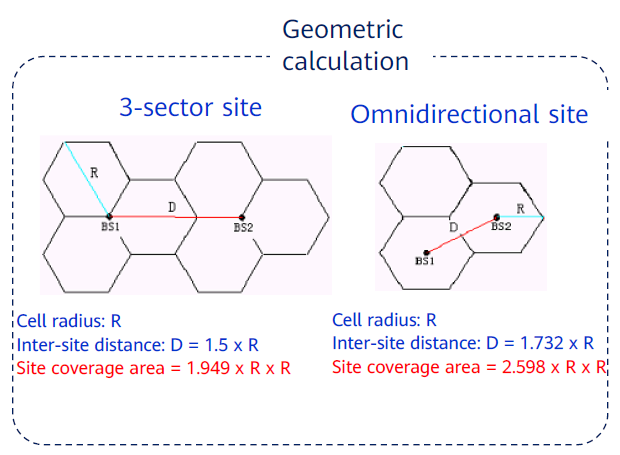

antenna_type="directive";
if antenna_type=="directive"
    Site_Area=1.949*(Cell_Range/1000)^2;
elseif antenna_type=="omni"
    Site_Area=2.598*(Cell_Range/1000)^2;
end
disp("Site Area = "+Site_Area+"km^2")

Site Area = 1.6408km^2



No_Site_Coverage=Area/Site_Area;
disp("Number of Sites = "+No_Site_Coverage)

Number of Sites = 3.0473


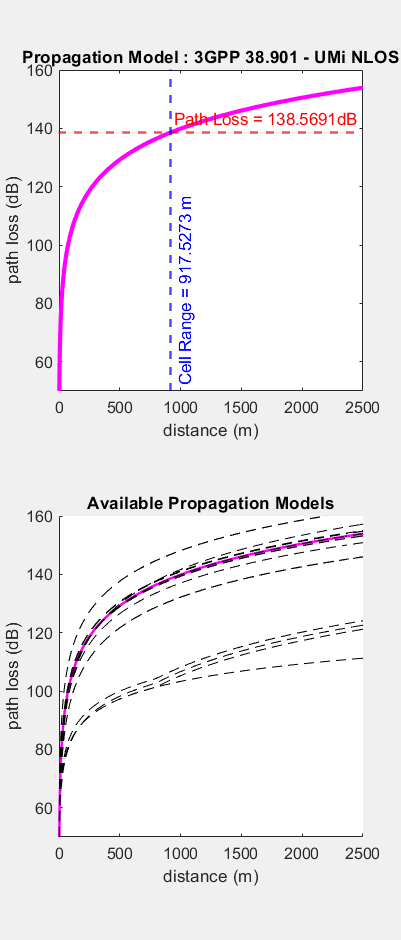


if exist("f1","var") && isvalid(f1)
    set(0,"CurrentFigure",f1);
else
    f1=figure("Name","Propagation Model","Visible","on","WindowStyle","docked",'NumberTitle','off');
end
subplot(2,1,1);
plot(p_y,p_x,"m","LineWidth",2.5);
xlabel("distance (m)");
ylabel("path loss (dB)");

title("Propagation Model : "+pm+" - "+senario);

xlim([0 2500]);
ylim([50 160]);
yline(MAPL,'--r','Path Loss = '+ string(MAPL)+"dB","LineWidth",1.5);
xline(Cell_Range,'--b',"Cell Range = "+Cell_Range+" m",'LabelVerticalAlignment','bottom',"LineWidth",1.5);
f1.Name="Propagation Model : "+pm+" - "+senario;

#### Important Links for Link Budget Calculations:

- [https://5g-tools.com/5g-nr-link-budget-calculator/](https://5g-tools.com/5g-nr-link-budget-calculator/)

- [https://nrcalculator.firebaseapp.com/nrlinkbudget.html](https://nrcalculator.firebaseapp.com/nrlinkbudget.html)